% Clear persistent state variables and buffers, and close all figures
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMChannel helperOFDMFrequencyOffset
close all;

userParam = struct( ...
    'BWIndex',          4, ...   % Index corresponding to desired bandwidth
    'modOrder',         2, ...   % Subcarrier constellation modulation order
    'codeRateIndex',    0, ...   % Code rate index corresponding to desired rate
    'numSymPerFrame',   15, ...   % Number of OFDM symbols per frame
    'numFrames',        100, ...   % Number of frames to be generated for simulation (12-500)
    'fc',               1900000000, ...   % Carrier frequency (Hz)
    'enableFading',     true                 , ...   % Enable/disable channel fading
    'chanVisual',       "Off", ...   % Channel fading visualization option
    'enableCFO',        true                 , ...   % Enable/disable carrier frequency offset compensation
    'enableCPE',        true                 , ...   % Enable/disable common phase error compensation
    'enableScopes',     true                 , ...   % Enable/disable scopes
    'verbosity',        0);      % Diagnostic output verbosity

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 72;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 30e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 3e6;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 2;   % Data modulation order
dataParams.coderate       = "1/2";   % Code rate
dataParams.numSymPerFrame = 15;   % Number of data symbols per frame 20 for setup1
dataParams.numFrames      = 100;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = false;                    % Switch to enable or disable the data diagnostic output

radioDevice            = "PLUTO";  % Choose the radio device for transmission
centerFrequency        = 3e9;  % Center Frequency
gain                   = 0;  % Set radio gain

[sysParam,txParam,trBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);

'helperOFDMSetParamsSDR' is used in the following examples:
  OFDM Receiver Using Software Defined Radio
  OFDM Transmitter Using Software-Defined Radio 

sampleRate               = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
ofdmTx                   = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain);

% Get the radio transmitter and spectrum analyzer system object system object for the user to visualize the transmitted waveform.
[radio,spectrumAnalyze] = helperGetRadioTxObj(ofdmTx);

SNRdB = 0:5:30; % SNR in dB
v     = 40; % mobile velocity (km/h)     
foff  = 3.25; % frequency offset (ppm)
fadingPathDelays =  [0 0.1e-6 0.3e-6];
fadingPathGains  =  [0 1 -9];

BERResults = zeros(size(SNRdB));

[sysParam, txParam] = helperOFDMSetParameters(userParam);

[~,codeParam] = helperOFDMGetTables(userParam.BWIndex,userParam.codeRateIndex);
codeRate = codeParam.codeRate; % Coding rate

fprintf('\nTransmitting at %d MHz with an occupied bandwidth of %d MHz\n', ...
    sysParam.fc/1e6,sysParam.scs*sysParam.usedSubCarr/1e6);


Transmitting at 1900 MHz with an occupied bandwidth of 9 MHz


% Calculate fading channel impairments
KPH_TO_MPS = (1000/3600);
fsamp = sysParam.scs*sysParam.FFTLen;       % sample rate of signal
T = (sysParam.FFTLen+sysParam.CPLen)/fsamp; % symbol duration (s)
fmax = v * KPH_TO_MPS * sysParam.fc / physconst('LightSpeed');  % Maximum Doppler shift of diffuse components (Hz)

% Set up scopes
if userParam.enableScopes
    % Set up constellation diagram object
    refConstHeader = qammod(0:1,2,UnitAveragePower=true); % header is always BPSK
    refConstData   = qammod(0:txParam.modOrder-1,txParam.modOrder,UnitAveragePower=true);
    constDiag = comm.ConstellationDiagram(2, ...
        "ChannelNames",{'Header','Data'}, ...
        "ReferenceConstellation",{refConstHeader,refConstData}, ...
        "ShowLegend",true, ...
        "EnableMeasurements",true);

    % Set up spectrum analyzer visualization object
    sa = spectrumAnalyzer( ...
        'Name',             'Signal Spectra', ...
        'Title',            'Transmitted and Received Signal', ...
        'SpectrumType',     'Power', ...
        'FrequencySpan',    'Full', ...
        'SampleRate',       fsamp, ...
        'ShowLegend',       true, ...
        'Position',         [100 600 800 500], ...
        'ChannelNames',     {'Transmitted','Received'});
end

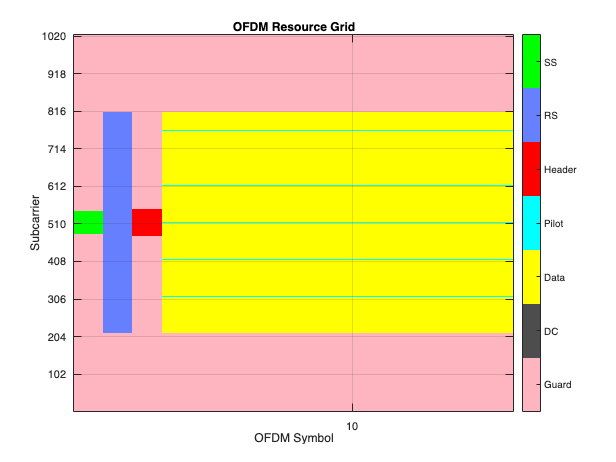

% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);


% Initialize receiver
rxObj = helperOFDMRxInit(sysParam);
    
for simLoopIdx = 1:length(SNRdB)
    % Configure the channel
    chanParam = struct( ...
        'SNR',       SNRdB(simLoopIdx), ...
        'foff',      foff, ...       % normalized frequency offset (ppm)
        'doppler',   fmax*T, ...     % normalized Doppler frequency
        'pathDelay', fadingPathDelays, ...
        'pathGain',  fadingPathGains);
    fprintf('Configuring the fading AWGN channel at %d dB SNR and %d kph...\n', SNRdB(simLoopIdx), v);

    sysParam.txDataBits = []; % clear tx data buffer

    sysParam.timingAdvance = (sysParam.FFTLen + sysParam.CPLen) * ...
        sysParam.numSymPerFrame; % set sample buffer timing advance
    
    % Instantiate an ErrorRate object to cumulatively track BER
    errorRate = comm.ErrorRate();

    fprintf('Transmitting %d frames with transport block size of %d bits per frame...\n', ...
        sysParam.numFrames,sysParam.trBlkSize);
    fprintf('Searching for synchronization symbol...');
    % Loop through all frames. Generate one extra frame to obtain the
    % reference symbol for channel estimates of the last frame.
    for frameNum = 1:sysParam.numFrames+1
        sysParam.frameNum = frameNum;
        % Generate random data to transmit. Replace with user data if desired.
        txParam.txDataBits  = randi([0 1],sysParam.trBlkSize,1);

        % Store data bits for BER calculations
        sysParam.txDataBits = [sysParam.txDataBits; txParam.txDataBits];
        sysParam.txDataBits = sysParam.txDataBits(max(1,end-2*sysParam.trBlkSize):end);
        % Transmit data
        [txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);
        % Process one frame of samples through channel
        chanOut = helperOFDMChannel(txOut,chanParam,sysParam);
        if userParam.enableScopes    
            sa(txOut,chanOut);
        end
        % Run the receiver front-end
        rxIn = helperOFDMRxFrontEnd(chanOut,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected    
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % system object
            BER = errorRate(...
                sysParam.txDataBits(end-(2*sysParam.trBlkSize)+(1:sysParam.trBlkSize)), ...
                rxDataBits);
        end
        if isConnected && userParam.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                      complex(rxDiagnostics.rxConstellationData(:)));
        end
    end % frame loop
    % Clear out the |persistent| variables for the sync detection flag and
    % camped flag
    clear helperOFDMRx;
    clear helperOFDMRxSearch;

    % Compute data diagnostics
    if isConnected
        FER = sum(rxDiagnostics.dataCRCErrorFlag) / length(rxDiagnostics.dataCRCErrorFlag);
        fprintf('Simulation completed at %d SNR: BER = %d, FER = %d\n',SNRdB(simLoopIdx),BER(1),FER);
        BERResults(simLoopIdx) = BER(1);
    else
        fprintf('Simulation completed at %d SNR: Base station not detected.\n',SNRdB(simLoopIdx));
        fprintf('\n');
        BERResults(simLoopIdx) = 0.5; % default to high BER for plotting purposes
    end

    % Release object to reconfigure for the next simulation run
    release(errorRate);
    
% SNR loop end
end

Configuring the fading AWGN channel at 0 dB SNR and 40 kph...


Transmitting 100 frames with transport block size of 6802 bits per frame...


Searching for synchronization symbol...

.....................................................................................................

Simulation completed at 0 SNR: Base station not detected.


Configuring the fading AWGN channel at 5 dB SNR and 40 kph...


Transmitting 100 frames with transport block size of 6802 bits per frame...


Searching for synchronization symbol...

.........
Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
...........................................................
.....................

Simulation completed at 5 SNR: BER = 1.845211e-01, FER = 8.250000e-01


Configuring the fading AWGN channel at 10 dB SNR and 40 kph...


Transmitting 100 frames with transport block size of 6802 bits per frame...


Searching for synchronization symbol...

........
Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
............................................................
.....................

Simulation completed at 10 SNR: BER = 6.816623e-02, FER = 7.283951e-01


Configuring the fading AWGN channel at 15 dB SNR and 40 kph...


Transmitting 100 frames with transport block size of 6802 bits per frame...


Searching for synchronization symbol...


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
....................................................................
.....................

Simulation completed at 15 SNR: BER = 1.508314e-02, FER = 3.932584e-01


Configuring the fading AWGN channel at 20 dB SNR and 40 kph...


Transmitting 100 frames with transport block size of 6802 bits per frame...


Searching for synchronization symbol...


Sync symbol found.
Estimating carrier frequency offset .............
Receiver camped.
..........................................................

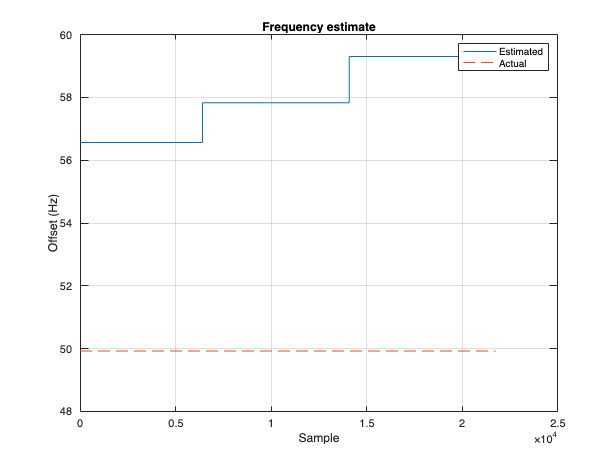

% Plot the transmission grid
helperOFDMPlotResourceGrid(txGrid,sysParam);

% Plot the frequency offset estimator output
figure;
plot(rxDiagnostics.estCFO*sysParam.scs);
hold on;
plot(foff*fsamp*ones(length(rxDiagnostics.estCFO),1)/1e6,'--');
title('Frequency estimate');
xlabel('Sample');
ylabel('Offset (Hz)');
grid on;
legend('Estimated','Actual');


% Plot the channel estimate for one subcarrier
figure;
plot(real(rxDiagnostics.estChannel(3,:)));
hold on;
plot(imag(rxDiagnostics.estChannel(3,:)));
title('Channel estimate, subcarrier 3');
xlabel('Symbol');
ylabel('Magnitude');
grid on;
legend('Real','Imag');


% Plot a BER curve if more than one SNR was specified
if length(SNRdB) > 1
    figure;
    semilogy(SNRdB,BERResults+eps,'-*'); % add eps if no errors found
    title('BER curve');
    xlabel('SNR (dB)');
    ylabel('BER');
    grid on;
end